Analaysis

% housekeeping 

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions', filesep);
addpath(genpath(function_folder))

d = struct;
cfg = struct;

% get subject numbers
cfg.exp_name = 'free'; % 'free' or 'gazeCon'
if strcmp(cfg.exp_name, 'free')
    cfg.subNums = 4:37;
elseif strcmp(cfg.exp_name, 'gazeCon')
    cfg.subNums = [102:108, 110:136];
end
cfg.n = length(cfg.subNums);

% other standard configurations
cfg.categories = {'bathroom', 'kitchen'};
cfg.colormaps = load('white_zero_colormap.mat');
cfg.FontName = 'Helvetica';
cfg.FontSize = 15;


% load images and get DNN representation
images = load_images(cfg);

Loaded image: 102_bath1_3D.png
Loaded image: 102_bath2_3D.png
Loaded image: 102_bath3_3D.png
Loaded image: 103_bath1_3D.png
Loaded image: 103_bath2_3D.png
Loaded image: 103_bath3_3D.png
Loaded image: 104_bath1_3D.png
Loaded image: 104_bath2_3D.png
Loaded image: 104_bath3_3D.png
Loaded image: 105_bath1_3D.png
Loaded image: 105_bath2_3D.png
Loaded image: 105_bath3_3D.png
Loaded image: 106_bath1_3D.png
Loaded image: 106_bath2_3D.png
Loaded image: 106_bath3_3D.png
Loaded image: 107_bath1_3D.png
Loaded image: 107_bath2_3D.png
Loaded image: 107_bath3_3D.png
Loaded image: 108_bath1_3D.png
Loaded image: 108_bath2_3D.png
Loaded image: 108_bath3_3D.png
Loaded image: 110_bath1_3D.png
Loaded image: 110_bath2_3D.png
Loaded image: 110_bath3_3D.png
Loaded image: 111_bath1_3D.png
Loaded image: 111_bath2_3D.png
Loaded image: 111_bath3_3D.png
Loaded image: 112_bath1_3D.png
Loaded image: 112_bath3_3D.png
Loaded image: 113_bath1_3D.png
Loaded image: 113_bath2_3D.png
Loaded image: 113_bath3_3D.png
Loaded i

analysis typical - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


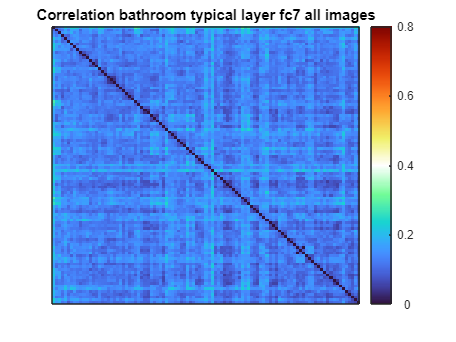

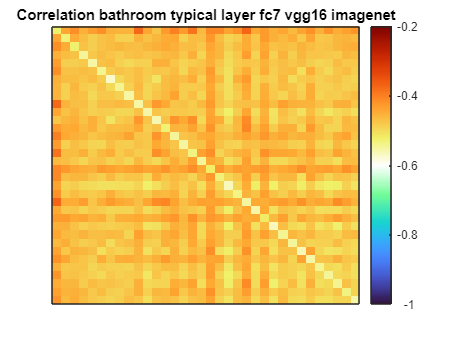

analysis typical - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


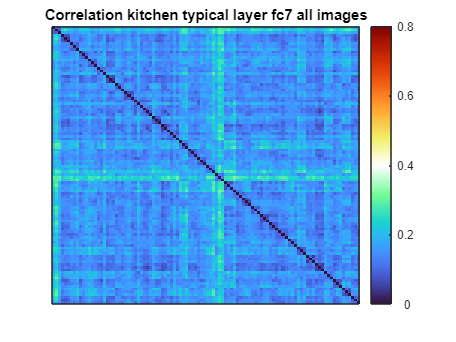

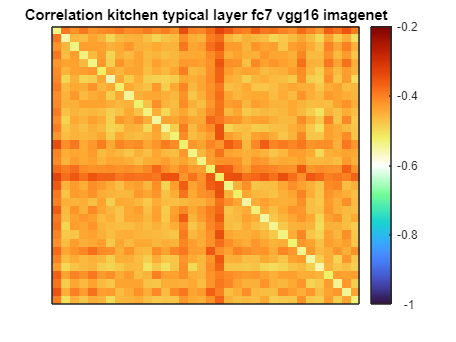


% typical images 
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


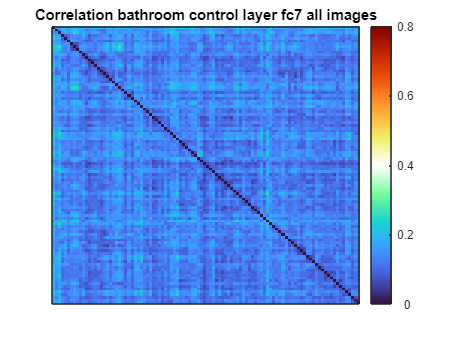

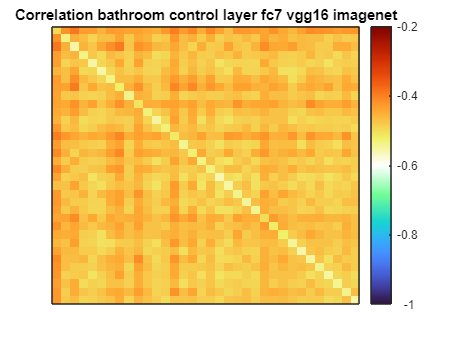

analysis control - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


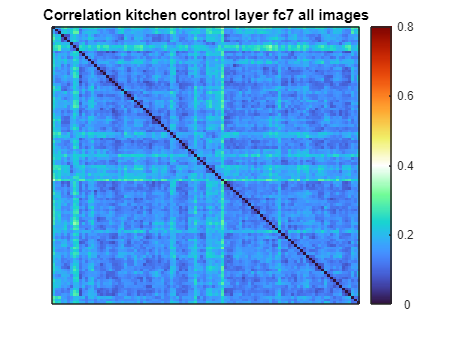

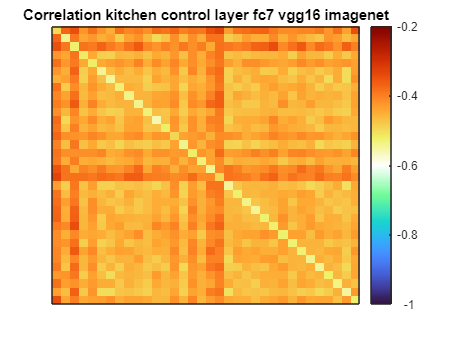


% control images 
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

Gaze

%a_preprocessing(cfg)
%b_detFix(cfg)
%c_showFix
%d_AOIfix(cfg)

cfg.minNumPerCate = 5;
e_getGazePatterns(cfg);

Subject 102 already exists
Subject 103 already exists
Subject 104 already exists
Subject 105 already exists
Subject 106 already exists
Subject 107 already exists
Subject 108 already exists
Subject 110 already exists
Subject 111 already exists
Subject 112 already exists
Subject 113 already exists
Subject 114 already exists
Subject 115 already exists
Subject 116 already exists
Subject 117 already exists
Subject 118 already exists
Subject 119 already exists
Subject 120 already exists
Subject 121 already exists
Subject 122 already exists
Subject 123 already exists
Subject 124 already exists
Subject 125 already exists
Subject 126 already exists
Subject 127 already exists
Subject 128 already exists
Subject 129 already exists
Subject 130 already exists
Subject 131 already exists
Subject 132 already exists
Subject 133 already exists
Subject 134 already exists
Subject 135 already exists
Subject 136 already exists
Subject 102 already exists
Subject 103 already exists
Subject 104 already exists
S

e_getGazePatterns_firstFix(cfg);

Subject 102 already exists
Subject 103 already exists
Subject 104 already exists
Subject 105 already exists
Subject 106 already exists
Subject 107 already exists
Subject 108 already exists
Subject 110 already exists
Subject 111 already exists
Subject 112 already exists
Subject 113 already exists
Subject 114 already exists
Subject 115 already exists
Subject 116 already exists
Subject 117 already exists
Subject 118 already exists
Subject 119 already exists
Subject 120 already exists
Subject 121 already exists
Subject 122 already exists
Subject 123 already exists
Subject 124 already exists
Subject 125 already exists
Subject 126 already exists
Subject 127 already exists
Subject 128 already exists
Subject 129 already exists
Subject 130 already exists
Subject 131 already exists
Subject 132 already exists
Subject 133 already exists
Subject 134 already exists
Subject 135 already exists
Subject 136 already exists
Subject 102 already exists
Subject 103 already exists
Subject 104 already exists
S


cfg.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectDwellsCateEven', 'ObjectDwellsCateOdd',...
    'ObjectsCate_firstFix', 'ObjectsCate_firstFixEven', 'ObjectsCate_firstFixOdd',...
    'IndividualObjectDwells', 'IndividualObjects_firstFix',...
    'ObjectCatePrio', 'ObjectCatePrioOdd', 'ObjectCatePrioEven'};
 d = makeGDM(d, cfg);
 d = regressOutMean(d, cfg);


Get inter-subject correlation

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom


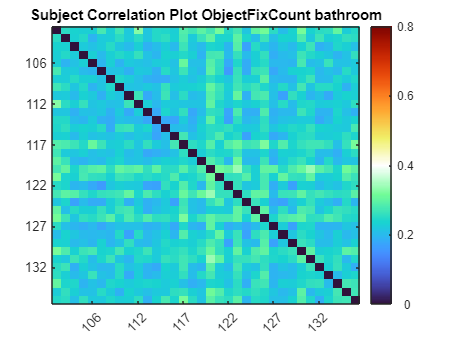

Plotting and saving inter-subject RDM for task:ObjectDwellsCate and bathroom


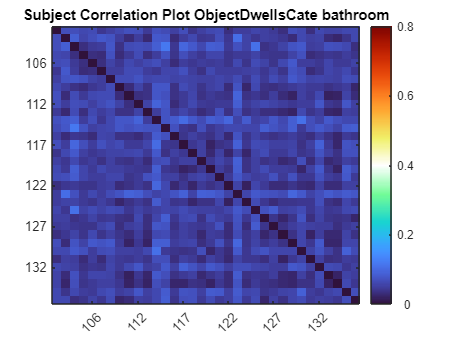

Plotting and saving inter-subject RDM for task:ObjectDwellsCateEven and bathroom


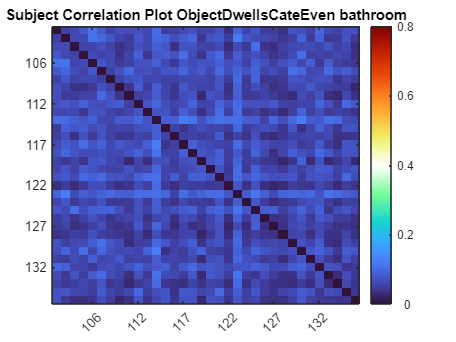

Plotting and saving inter-subject RDM for task:ObjectDwellsCateOdd and bathroom


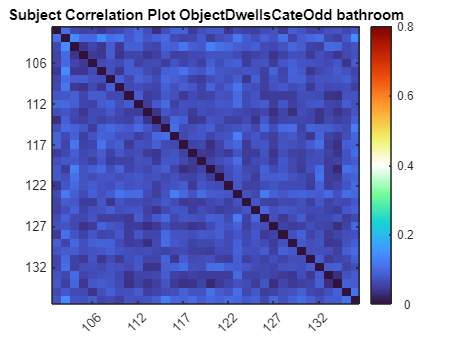

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and bathroom


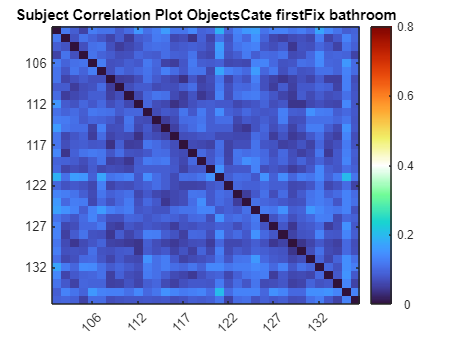

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixEven and bathroom


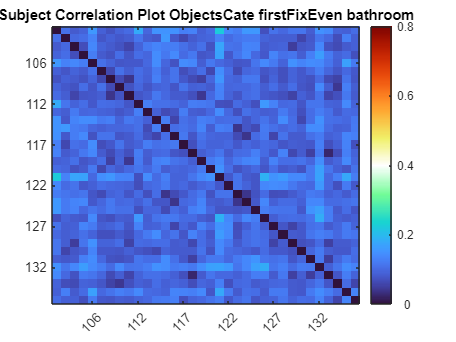

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixOdd and bathroom


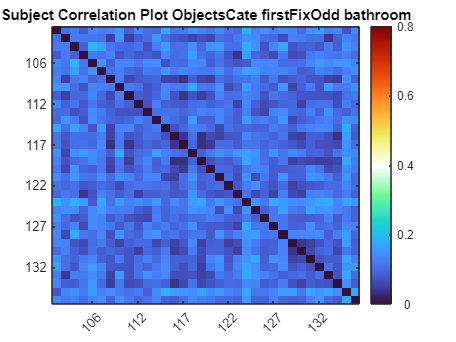

Plotting and saving inter-subject RDM for task:IndividualObjectDwells and bathroom


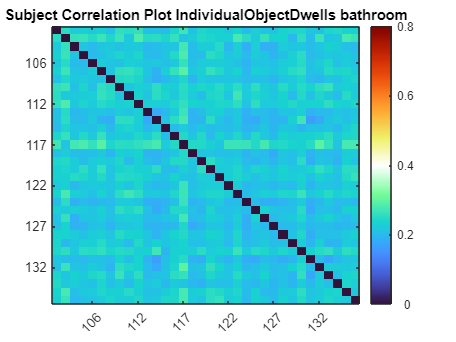

Plotting and saving inter-subject RDM for task:IndividualObjects_firstFix and bathroom


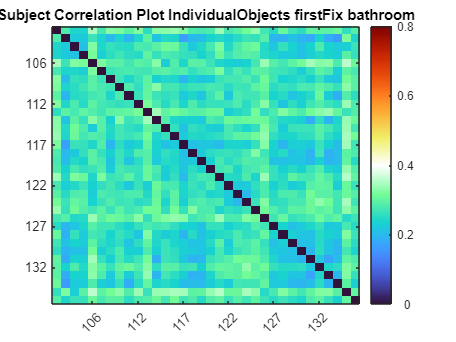

Plotting and saving inter-subject RDM for task:ObjectCatePrio and bathroom


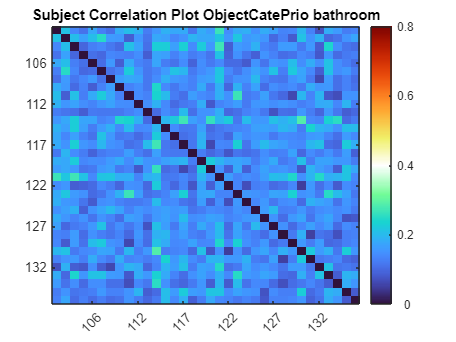

Plotting and saving inter-subject RDM for task:ObjectCatePrioOdd and bathroom


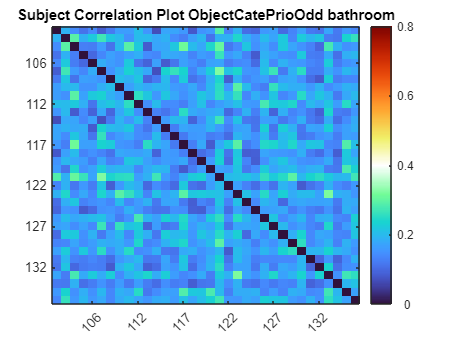

Plotting and saving inter-subject RDM for task:ObjectCatePrioEven and bathroom


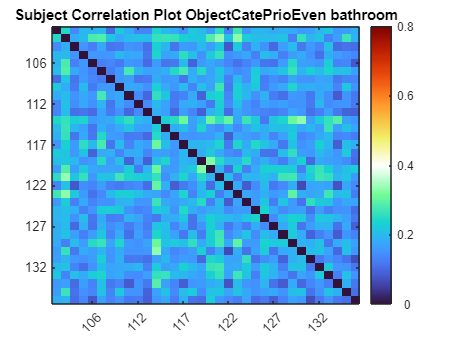

Plotting and saving inter-subject RDM for task:ObjectFixCount and kitchen


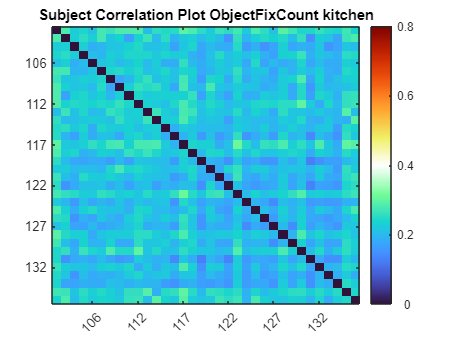

Plotting and saving inter-subject RDM for task:ObjectDwellsCate and kitchen


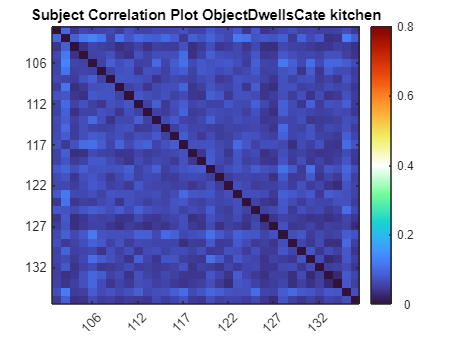

Plotting and saving inter-subject RDM for task:ObjectDwellsCateEven and kitchen


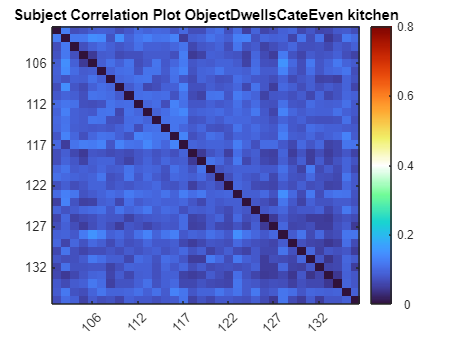

Plotting and saving inter-subject RDM for task:ObjectDwellsCateOdd and kitchen


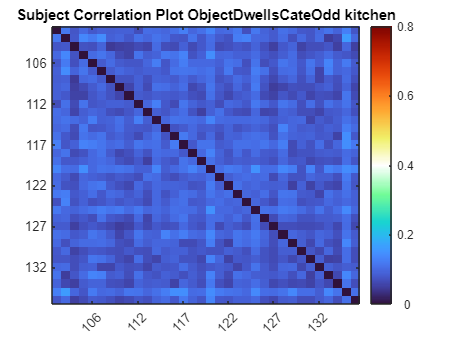

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and kitchen


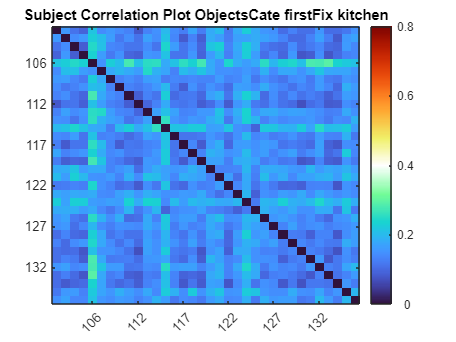

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixEven and kitchen


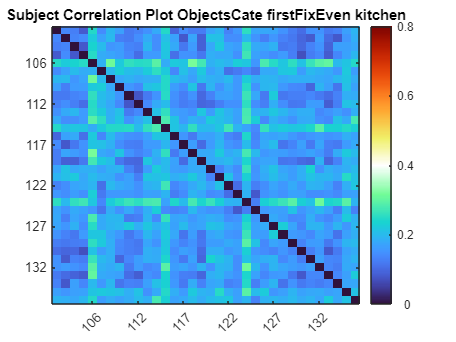

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixOdd and kitchen


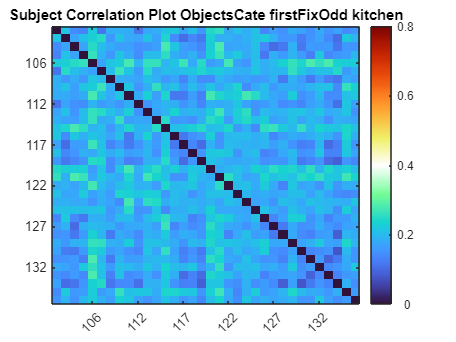

Plotting and saving inter-subject RDM for task:IndividualObjectDwells and kitchen


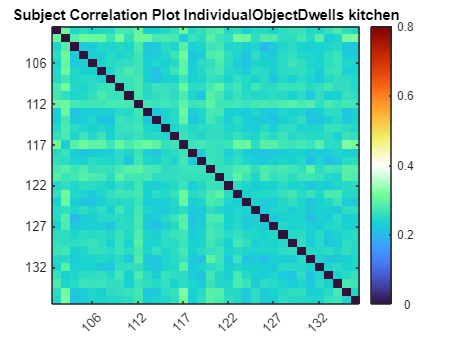

Plotting and saving inter-subject RDM for task:IndividualObjects_firstFix and kitchen


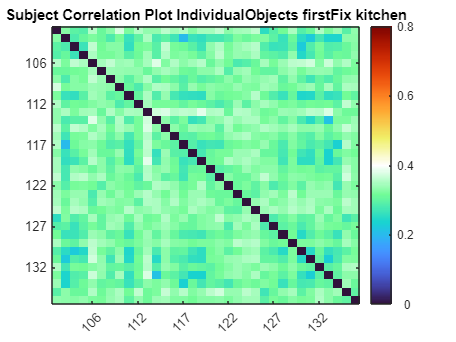

Plotting and saving inter-subject RDM for task:ObjectCatePrio and kitchen


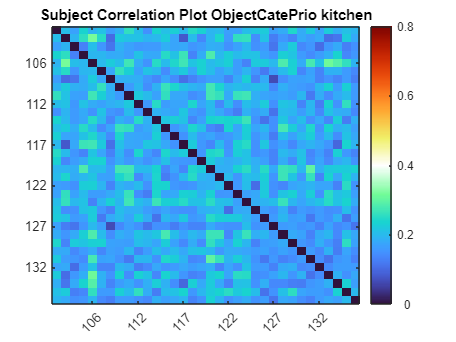

Plotting and saving inter-subject RDM for task:ObjectCatePrioOdd and kitchen


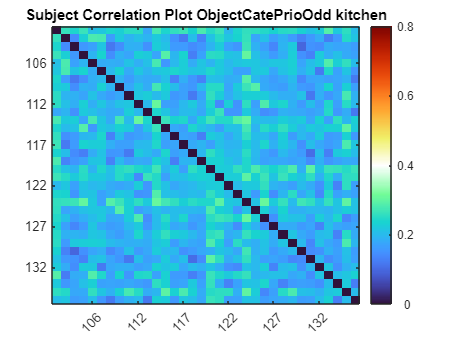

Plotting and saving inter-subject RDM for task:ObjectCatePrioEven and kitchen


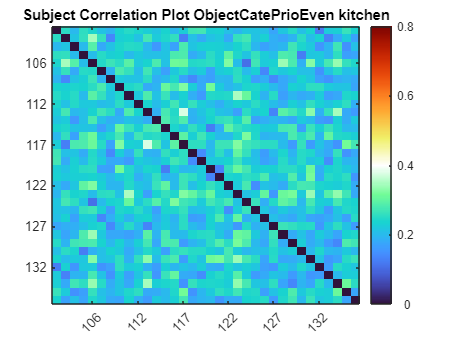

Compare categories


cfg.regressOutMean = false;
cfg.correlation_type = 'spearman';
d = intersub_cor(d, cfg);

Get gaze distance

d = getGazeDist(d, cfg);

Data exist already


Split half correlation

% split half correlation
cfg.regressOutMean = false;
% cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
%     'ObjectDwellsCate', 'ObjectsCate_firstFix',...
%     'IndividualObjectDwells', 'IndividualObjects_firstFix',...
%     'ObjectCatePrio'};
cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.correlation_type = 'pearson';
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
d = getSpliHalfReliability(d, cfg);

 
Fixation count
r: 0.26411, p = 2.0889e-10
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category dwell time
r: 0.215, p = 2.7306e-07
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category first fixation count
r: 0.26926, p = 8.9603e-11
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of perm

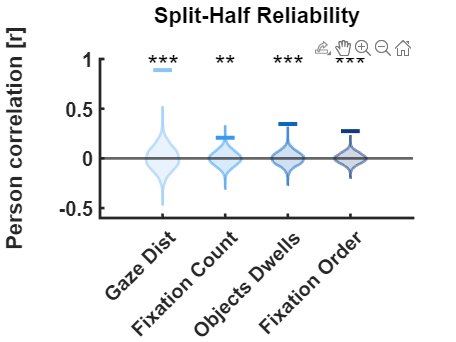

Gaze Dist
FDR corrected p value for Gaze Dist: 0
R value for Gaze Dist: 0.88848


Fixation Count
FDR corrected p value for Fixation Count: 0.0021
R value for Fixation Count: 0.2079


Objects Dwells
FDR corrected p value for Objects Dwells: 0
R value for Objects Dwells: 0.34557


Fixation Order
FDR corrected p value for Fixation Order: 0
R value for Fixation Order: 0.27452




plotSpliHalfReliability(d, cfg);

Compare them

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of GazeDist bathroom is done
20% of permutations of GazeDist bathroom is done
30% of permutations of GazeDist bathroom is done
40% of permutations of GazeDist bathroom is done
50% of permutations of GazeDist bathroom is done
60% of permutations of GazeDist bathroom is done
70% of permutations of GazeDist bathroom is done
80% of permutations of GazeDist bathroom is done
90% of permutations of GazeDist bathroom is done
100% of permutations of GazeDist bathroom is done
Compare inter-subject RDM of GazeDist with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of GazeDist kitchen is done
20% of permutations of GazeDist kitchen is done
30% of permutations of GazeDist kitchen is done
40% of permutations of GazeDist kitchen is done
50% of permutations of GazeDist kitchen is done
60% of permutations of GazeDist kitchen is done
70% of permut

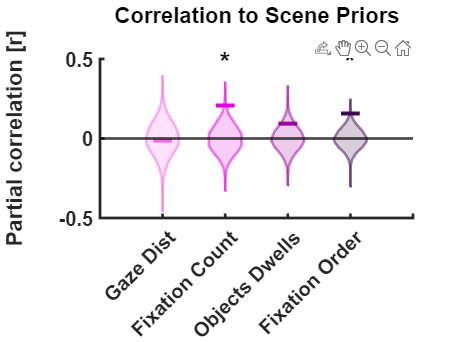

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'violin';
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.ylim = [-.5, .5];
cfg.partial_correlation_type = 'pearson';
cfg.fdr_correction = true;
cfg.plotting_predictors = 1;

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

Compare drawing oder and fixation order

cfg.partialCorr = false; % control for object size in stimuli
cfg.ylim = [-.4, .6];
d = evaluateDrawingOrder(d, cfg)


Compare gazeDist in bined time windows

% % preparation
% cfg.partial_cor = true;
% cfg.plot_rdm = false;
% cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
% cfg.predictor_RDMs = {'typical_late', 'control_late'};
% cfg.variables_of_interest = {'GazeDist'};
% cfg.dnns = {'vgg16_imagenet'};
% cfg.show_single_cate = false;
% cfg.ylim = [-.21, .41];
% cfg.partial_correlation_type = 'pearson';
% 
% d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

Get memory task performance

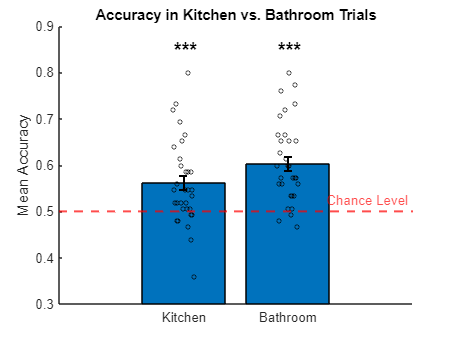

d = struct with fields:
                          DNN: [1×1 struct]
                          GDM: [1×1 struct]
                 GDM_demeaned: [1×1 struct]
                RDM_pwc_table: [12×3 table]
                 bathroom_RDM: [1×1 struct]
                  kitchen_RDM: [1×1 struct]
    compare_task_to_predictor: [1×1 struct]
                   memoryTask: [1×1 struct]


if strcmp(cfg.exp_name, 'gazeCon')
    d = getAccuracyMemoryTask(cfg, d)
end